s = tf('s');
A = [0 1 0 0; 0 0 -3.2667 0; 0 0 0  1; 0 0 19.6 0];
B = [0 0; 0.8889 -1.333; 0 0; -1.333 8];
C = [1 0 0 0; 0 0 1 0];
D = [0 0;0 0];
zpk(D+C*inv(s * eye(4) - A) * B)

ans =
 
  From input 1 to output...
       0.8889 s^2 (s-3.834) (s+3.834)
   1:  ------------------------------
          s^4 (s-4.427) (s+4.427)
 
             -1.333
   2:  -------------------
       (s+4.427) (s-4.427)
 
  From input 2 to output...
       -1.333 (s+2.545e-07) (s-2.545e-07) (s^2 + 0.005101)
   1:  ---------------------------------------------------
                     s^4 (s-4.427) (s+4.427)
 
                8
   2:  -------------------
       (s+4.427) (s-4.427)
 
Continuous-time zero/pole/gain model.



Atilda = [A zeros(4,2); C zeros(2,2)]

Atilda =          0    1.0000         0         0         0         0
         0         0   -3.2667         0         0         0
         0         0         0    1.0000         0         0
         0         0   19.6000         0         0         0
    1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0


Btilda = [B; zeros(2,2)]

Btilda =          0         0
    0.8889   -1.3330
         0         0
   -1.3330    8.0000
         0         0
         0         0


Mc = ctrb(Atilda, Btilda);
rank(Mc)

ans = 6

K = place(Atilda, Btilda, [-20, -20.01, -20.02, -19.99, -19.98, -20.03])

K = 1.0e+05 *

    0.0302    0.0012   -0.2428   -0.0060    0.2423   -2.4384
    0.0051    0.0002   -0.0399   -0.0009    0.0409   -0.4064


To confirm pole positions

eig(Atilda - Btilda * K)

ans =   -19.9794
  -20.0300
  -19.9900
  -20.0000
  -20.0198
  -20.0100


K1 = K(:,1:4);
K2 = K(:,5:end);
A_cls = [A-B*K1 -B*K2; C zeros(2,2)]

A_cls = 1.0e+05 *

         0    0.0000         0         0         0         0
   -0.0201   -0.0008    0.1625    0.0041   -0.1609    1.6258
         0         0         0    0.0000         0         0
   -0.0004   -0.0000   -0.0039   -0.0004   -0.0040    0.0008
    0.0000         0         0         0         0         0
         0         0    0.0000         0         0         0


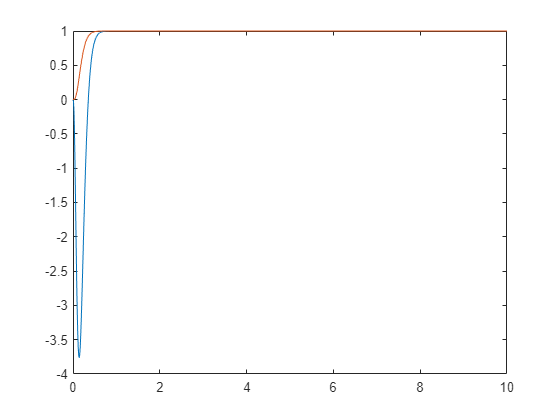

B_cls = [zeros(4, 2); -eye(2)];
C_cls = [C zeros(2, 2)];
D_cls= 0;
CLS = ss(A_cls, B_cls, C_cls, D_cls);
T = 0:0.01:10;
r = ones(2, length(T))';
y = lsim(CLS, r, T, [0 0 0 0 0 0]');
plot(T, y)

A2 = [0 1 0 0 0 0; 0 0 -4.41 0 0.49 0; 0 0 0 1 0 0; 0 0 61.74 0 -26.46 0;0 0 0 0 0 1;0 0 -79.38 0 67.62 0];
B2 = [0 0 0;0.9333 -2.40 0.80;0 0 0;-2.40 33.60 -43.20;0 0 0;0.80 -43.20 110.40];
C2 = [1 0 0 0 0 0;0 0 1 0 0 0;0 0 0 0 1 0];
D2 = [0 0 0;0 0 0;0 0 0];
zpk(D2+C2*inv(s * eye(6) - A2) * B2)

ans =
 
  From input 1 to output...
       0.9333 s^4 (s-10.52) (s-10.16) (s-4.331) (s-3.788) (s+4.331) (s+3.788) (s+10.16) (s+10.52)
   1:  ------------------------------------------------------------------------------------------
                          s^6 (s+10.52)^2 (s+4.331)^2 (s-4.331)^2 (s-10.52)^2
 
       -2.4 (s-10.52) (s-7.668) (s-4.331) (s+4.331) (s+7.668) (s+10.52)
   2:  ----------------------------------------------------------------
               (s-10.52)^2 (s-4.331)^2 (s+10.52)^2 (s+4.331)^2
 
       0.8 (s-10.52) (s-4.331) (s+10.52) (s+4.331) (s^2 + 176.4)
   3:  ---------------------------------------------------------
            (s-10.52)^2 (s-4.331)^2 (s+10.52)^2 (s+4.331)^2
 
  From input 2 to output...
                                                                                                                                      
       -2.4 s^2 (s-10.52) (s-7.668) (s-4.331) (s+4.331) (s+7.668) (s+10.52) (s-0.0002758) (s+0.0002758) (s^2 + 2.547e-08s + 

Mc2 = ctrb(A2, B2)

Mc2 = 1.0e+06 *

         0         0         0    0.0000   -0.0000    0.0000         0         0         0    0.0000   -0.0002    0.0002         0         0         0    0.0009   -0.0169    0.0300
    0.0000   -0.0000    0.0000         0         0         0    0.0000   -0.0002    0.0002         0         0         0    0.0009   -0.0169    0.0300         0         0         0
         0         0         0   -0.0000    0.0000   -0.0000         0         0         0   -0.0002    0.0032   -0.0056         0         0         0   -0.0169    0.3465   -0.6333
   -0.0000    0.0000   -0.0000         0         0         0   -0.0002    0.0032   -0.0056         0         0         0   -0.0169    0.3465   -0.6333         0         0         0
         0         0         0    0.0000   -0.0000    0.0001         0         0         0    0.0002   -0.0056    0.0109         0         0         0    0.0300   -0.6333    1.1803
    0.0000   -0.0000    0.0001         0         0         0    0.0002   -0.00

rank(Mc2)

ans = 6

K2 = place(A2, B2, [-20, -20.00001, -20.00002, -19.99999, -19.99998, -20.00003])

K2 =   600.0300   60.0030   75.0038    7.5004   25.0013    2.5001
   75.0038    7.5004   35.1713    3.3334   12.5002    1.2500
   25.0013    2.5001   12.5002    1.2500    8.9459    0.8333


To confirm pole positions

A_cls2 = A2 - B2* K2;
C_cls2 = C2 - D2 * K2;
eig(A_cls2)

ans =   -20.0000
  -20.0000
  -20.0000
  -20.0000
  -20.0000
  -20.0000


T2 = minreal(D2+C_cls2*inv(s * eye(6) - A_cls2) * B2);
zpk(T2)

ans =
 
  From input 1 to output...
                                                                        
                                                        0.9333 (s+20)^16
                                                                        
   1:  -------------------------------------------------------------------------------------------------------------------
                                                                                                                          
       (s+26.43) (s+15.16) (s^2 + 30.68s + 237.5) (s^2 + 51.74s + 675.4) (s^2 + 31.83s + 261.4) (s^2 + 33.8s + 302.7)     
                                                                                                                          
                               (s^2 + 48.71s + 612.6) (s^2 + 36.67s + 362.6) (s^2 + 44.61s + 527.7) (s^2 + 40.38s + 439.8)
                                                                                                                          
 
     

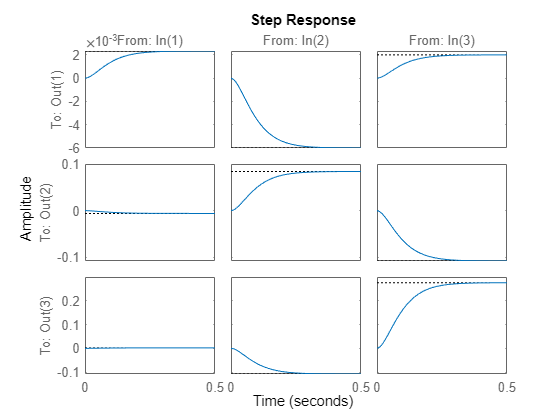

step(T2)